% 输入数据
low = [7.6 8.2 6.8 5.8 6.9 6.6 6.3 7.7 6.0];
mid = [6.7 8.1 9.4 8.6 7.8 7.7 8.9 7.9 8.3 8.7 7.1 8.4];
high = [8.5 9.7 10.1 7.8 9.6 9.5];

% 对数据进行单因素方差分析
groups = [repmat({'Low'}, size(low)), repmat({'Mid'}, size(mid)), repmat({'High'}, size(high))];
[p, tbl, stats] = anova1([low, mid, high], groups, 'off');

% 输出p值
fprintf('p value = %.4f\n', p);

p value = 0.0000


if p < 0.05
    fprintf('The difference between the groups is statistically significant.\n');
else
    fprintf('The difference between the groups is not statistically significant.\n');
end

The difference between the groups is statistically significant.


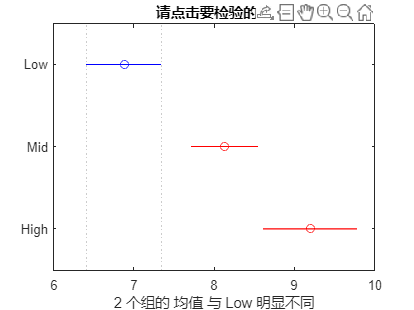


% 计算每组的95%置信区间
ci = multcompare(stats);


% 输出置信区间
for i = 1:3
    fprintf('The 95%% confidence interval for group %d is [%.4f, %.4f]\n', i, ci(i,3), ci(i,5));
end

The 95% confidence interval for group 1 is [-2.1366, -0.3745]
The 95% confidence interval for group 2 is [-3.3752, -1.2692]
The 95% confidence interval for group 3 is [-2.0657, -0.0677]


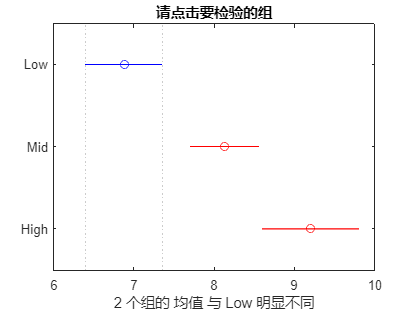


% 计算差值的95%置信区间
diff_ci = multcompare(stats, 'Estimate', 'row', 'CType', 'bonferroni');


% 输出差值的置信区间
for i = 1:size(diff_ci, 1)
    fprintf('The 95%% confidence interval for the difference between group %d and group %d is [%.4f, %.4f]\n', diff_ci(i,1), diff_ci(i,2), diff_ci(i,4), diff_ci(i,6));
end

The 95% confidence interval for the difference between group 1 and group 2 is [-1.2556, 0.0048]
The 95% confidence interval for the difference between group 1 and group 3 is [-2.3222, 0.0000]
The 95% confidence interval for the difference between group 2 and group 3 is [-1.0667, 0.0405]


% 输入数据
low = [7.6 8.2 6.8 5.8 6.9 6.6 6.3 7.7 6.0];
mid = [6.7 8.1 9.4 8.6 7.8 7.7 8.9 7.9 8.3 8.7 7.1 8.4];
high = [8.5 9.7 10.1 7.8 9.6 9.5];

% 对数据进行单因素方差分析
groups = [repmat({'Low'}, size(low)), repmat({'Mid'}, size(mid)), repmat({'High'}, size(high))];
[p, tbl] = anova1([low, mid, high], groups, 'off');

% 输出方差分析表
disp('ANOVA table:')

ANOVA table:


disp(tbl)

    {'来源'}    {'SS'     }    {'df'}    {'MS'      }    {'F'       }    {'p 值(F)'   }
    {'组'  }    {[20.1252]}    {[ 2]}    {[ 10.0626]}    {[ 15.7205]}    {[4.3307e-05]}
    {'误差'}    {[15.3622]}    {[24]}    {[  0.6401]}    {0×0 double}    {0×0 double  }
    {'合计'}    {[35.4874]}    {[26]}    {0×0 double}    {0×0 double}    {0×0 double  }

